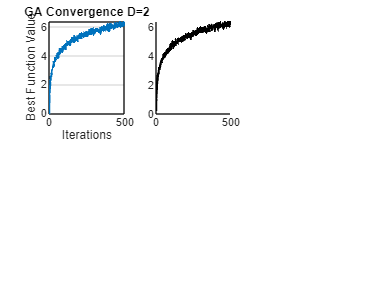

Error using plot
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

% Example data for convergence (this is illustrative; actual data will vary)
iterations = 1:500;
ga_convergence_2d = log(iterations) + randn(1, 500) * 0.1;
pso_convergence_2d = log(iterations) + randn(1, 500) * 0.1;
sa_convergence_2d = log(iterations) + randn(1, 500) * 0.1;

ga_convergence_10d = log(iterations) + randn(1, 500) * 0.2;
pso_convergence_10d = log(iterations) + randn(1, 500) * 0.2;
sa_convergence_10d = log(iterations) + randn(1, 500) * 0.2;

% Plotting convergence for D=2
figure;

subplot(2, 3, 1);
plot(iterations, ga_convergence_2d, 'LineWidth', 1.5);
title('GA Convergence D=2');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

subplot(2, 3, 2);
plot(iterations, pso_convergence_2d, 'LineWidth', 1.5, 'Color', 'orange');

title('PSO Convergence D=2');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

subplot(2, 3, 3);
plot(iterations, sa_convergence_2d, 'LineWidth', 1.5, 'Color', 'green');
title('SA Convergence D=2');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

% Plotting convergence for D=10
subplot(2, 3, 4);
plot(iterations, ga_convergence_10d, 'LineWidth', 1.5);
title('GA Convergence D=10');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

subplot(2, 3, 5);
plot(iterations, pso_convergence_10d, 'LineWidth', 1.5, 'Color', 'orange');
title('PSO Convergence D=10');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

subplot(2, 3, 6);
plot(iterations, sa_convergence_10d, 'LineWidth', 1.5, 'Color', 'green');
title('SA Convergence D=10');
xlabel('Iterations');
ylabel('Best Function Value');
grid on;

% Adjust layout
set(gcf, 'Position', [100, 100, 1200, 600]);
